# Maximizing Solar Panel Output for a Fixed Area

In this project, our team **Solar Panel Team #3** designed a solution to identify the **optimal tilt angle** and **optimal aspect ratio** of a solar panel to deliver the **maximal energy output** given environmental constraints. Additionally this project maps the optimal energy output onto a surf plot to illustrate how energy output is dependent on tilt angle and aspect ratio. 

## MODEL 1: Maximizing Energy Output given fixed constraints

The purpose of this model was to provide a way of finding the Maximum Energy Output given fixed environmental constraints

### Objective 1: Define the Objective Function 

The **Energy function **$E\left(\theta ,r\right)\;$is the objective function for this optimization problem. It calculates how much energy a solar panel produces based on its **Tilt Angle (theta) **and** Aspect Ratio (r)**

 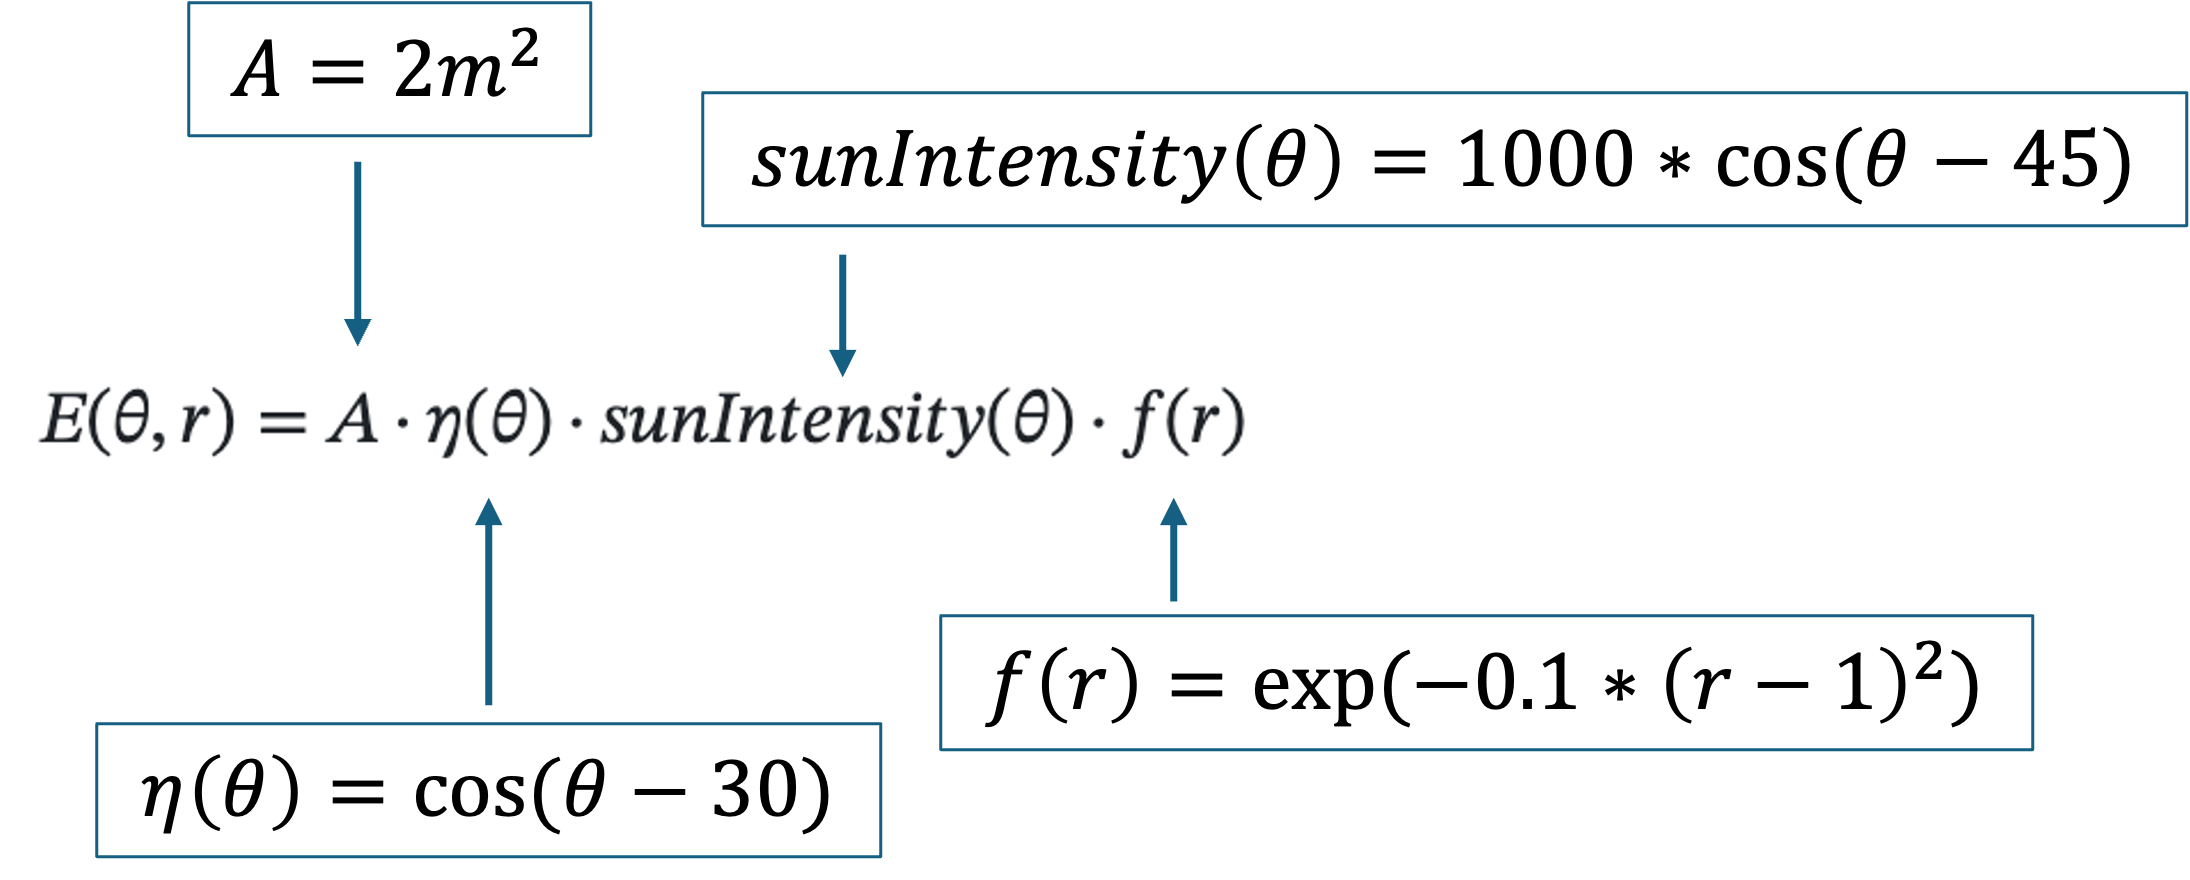

Note: The function "cosd" calculates values in degrees instead of radians 

% Step 1: Use the "function" command to build the objective function "energyOutput"
    function E = energyOutput(theta, r)

% Step 2: Define "A" (the fixed panel area) as 2m^2
        A = 2; 

% Step 3: Define "nu" (the angle efficiency) in terms of the optimization variable theta 
        nu = cosd(theta - 30); 

% Step 4: Define "fr" (shape efficiency factor) in terms of the optimization variable r
        fr = exp(-0.1 .* (r - 1).^2); 

% Step 5: Define "Sun_Intensity" (variation in sunlight) in terms of the optimization variable theta
        sun_intensity = 1000 .* cosd(theta - 45); 

% Step 6: Define the Objective Function "E" (Total Energy Output) in terms of "A", "nu", "Sun_Intensity" & "fr" which are in terms of "theta" and "r"
        E  = A .* nu .* sun_intensity .* fr;
    end


### Objective 2: Implement the Optimization Problem

The [optimization problem](https://www.mathworks.com/help/releases/R2026a/optim/ug/problem-based-workflow.html) solves for the **Maximum Energy Output**. 

% Step 1: Define the Optimization Problem (Solar_Max). Give it a description ("Description") of its purpose and solve for Maximum Value Output ("maximize")
    Solar_Max = optimproblem("Description","The Maximal Energy Output","ObjectiveSense","maximize");


By defining the optimization variables **Tilt Angle **(theta) and **Aspect Ratio **(r), the solver finds the highest energy output given the fixed constraints of Tilt Angle and Aspect Ratio. 

In Model 1, the environmental **Constraints are Fixed,** based off a theoretical assumption given in the project description. 

- Constraint for Tilt Angle: $0\degree \le \theta \le 90\degree$

- Constraint for Aspect Ratio: $0\ldotp 5\le r\le 4$ 

% Step 2: Define Optimization Variables and set Constraints

    % Constrain the lowest possible tilt angle to 0 degrees and the highest to 90 degrees  
        theta = optimvar("theta","lowerbound",0, "UpperBound",90);

    % Constrain the lowest possible aspect ratio to 0.5 and highest to 4 
        r = optimvar("r","lowerbound",0.5,"UpperBound", 4);

% Step 3: Create the Objective Function (Solar_Max.Objective) using "fcn2optimexpr"
    Solar_Max.Objective = fcn2optimexpr(@energyOutput, theta, r);

% Step 4: Set up the Initial Guess for "theta" and "r" (choose values within the constraints)
    initial_guess.theta = 45;
    initial_guess.r = 2;

% Step 5: Use the solve function to find the optimal Aspect ratio & Tilt angle which delivers the Maximum Energy Output
    [ solution, maxE ] = solve(Solar_Max,initial_guess);


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Step 6: Store Results
    Optimal_theta = solution.theta;
    Optimal_ratio = solution.r;
    Optimal_energy = maxE;

### Objective 3: Output the Results

**Plot E(θ, r)** to visualize the energy as a surface plot using `meshgrid` and [surf](https://www.mathworks.com/help/releases/R2026a/matlab/ref/surf.html). Plot the optimal tilt angle and aspect ratio, and corresponding energy output onto the grid; the absolute maximum of the surface plot should align with the optimal point. Finally, print the optimal tilt angle and aspect ratio, and the Maximum energy output.

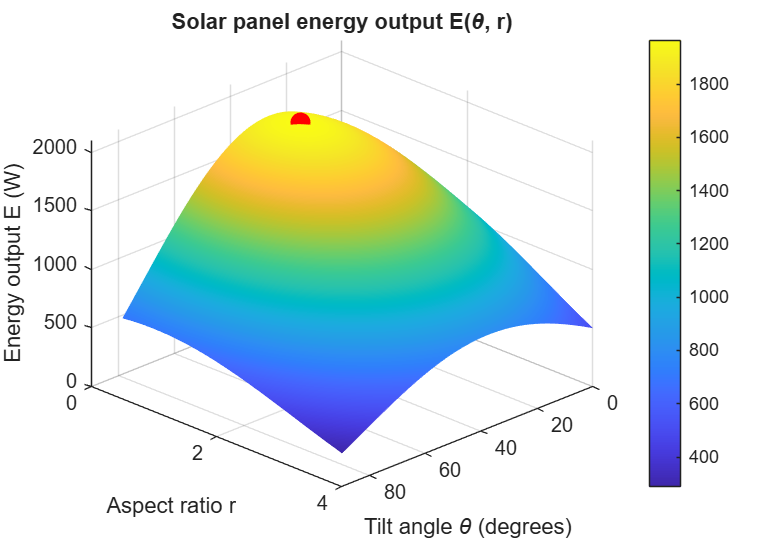

% Step 1: Create Grid Values for Tilt Angle and Aspect Ratio using meshgrid 

    % Set the lower bound to 0, the upper bound to 90 and the steps to 1
        theta_values = 0:1:90;

    % Set the lower bound to 0.5, the upper bound to 4 and the steps to 0.1
        r_values = 0.5:0.1:4;

    % Create the meshgrid 
        [theta_grid, r_grid] = meshgrid(theta_values,r_values);

% Step 2: Generate energy grid values that are dependent on the "theta_grid" and "r_grid" using the "energyOutput" function
        energy_grid = energyOutput(theta_grid, r_grid);

% Step 3: Use figure function to position the size and location of the plot 
    figure("Position",[100,100, 1000, 700]);

% Step 4: Create the Surface Plot using the surf function
        surf(theta_grid,r_grid,energy_grid);

    % Add shading that illustrate the gradual change in energy output using
    % shading and colorbar functions 
        shading interp;
        colorbar;

    % Set Axis limits for the plot (they can be equal to or greater then
    % constraints) 
        xlim([0 90]);
        ylim([0 4]);
        zlim([0 2100]);

    % The view function can be changed to gain a better camera line of 
    % sight of the surface plot   
        view(135, 30);

% Step 5: Label the plots
    xlabel("Tilt angle \theta (degrees)");
    ylabel("Aspect ratio r");
    zlabel("Energy output E (W)");
    title("Solar panel energy output E(\theta, r)");


% Step 6: Plot the optimal point on the surface plot
    hold on; 
    plot3(Optimal_theta, Optimal_ratio, Optimal_energy, "r.", "MarkerSize", 30);
    hold off;


% Step 7: Print Results
    fprintf("Optimal Tilt Angle  : %.2f degrees\n", solution.theta);

Optimal Tilt Angle  : 37.50 degrees


    fprintf("Optimal aspect ratio: %.2f\n", solution.r);

Optimal aspect ratio: 1.00


    fprintf("Maximum energy      : %.2f W/m^2\n", maxE);

Maximum energy      : 1965.93 W/m^2


### Interpretation of Results

    Through MATLAB's Optimization Toolbox™, Model 1 produced values consist of the maximum energy output. This can be seen through the optimal point plot aligning with the highest part of the surface plot representing the function $E\left(\theta ,r\right)$ within the fixed constraints. 

    In doing so, the model demonstrates the ability to find the optimal Tilt Angle and Aspect Ratio to deliver the maximum energy output for a solar panel with a fixed area of $2m^2$:

- Optimal Tilt Angle - $37\ldotp 50\degree$

- Optimal Aspect Ratio - 1.00

- The Maximum Energy Output - $1965\ldotp 93\;W/m^2$

    However, Model 1 is limited because of it's fixed constraints. It cannot be applied efficiently to a variety of situation where the constraints are not the given values. Additionally it does not account for the possibility of multiple local maximums that could provide misleading results based off its initial guess. 

    To improve on Model 1, a varying scale can be implemented that provides a more efficient and flexible program. This has more practical applications to commercial usage. Moreover, to account for the possibility of multiple local maximums, this new program must contain multiple initial guesses and also be able to sort through contradicting maximum values and provide the optimal Tilt Angle & Aspect Ratio for the highest maximum energy output. 